# Optimisation Statistique et Dynamique

TP1 - Optimisation Discrete et Continue

 jours 14/11 et 23/11/22

ENSEM ISN deuxième année 

Déric Augusto FRANCA DE SALES

Michelle FERREIRA MARTINS

*document généré par le fichier Matlab Live Script (contient les codes utilisés et les réponses aux questions et exercices proposés dans l'ordre, comme résumé ci-dessous).

clc; clear all; close all;

## l’algorithme du gradient descent

### faire la fonction qui génère la surface

Calcul du jacobien de la fonction pour écrire la fonction gradient_ma_fonction :

syms x y
f = -3.*exp(-(x-1).^2-(y-2).^2) + ((1-x).^2).*exp(-(x+1).^2-(y-1).^2) ...
    - 2.*((x/5)-(x.^3)-(y.^5)).*exp(- x.^2 - y.^2) ...
    - (1/2).*exp(-(x+1).^2 - y.^2) + 0.1.*(x.^2+  y.^2);    
g = string(jacobian(f))

g = 1×2 string array
    "x/5 + (exp(- (x + 1)^2 - y^2)*(2*x + 2))/2 + exp(- x^2 - y^2)*(6*x^2 - 2/5) + exp(- (x + 1)^2 - (y - 1)^2)*(2*x - 2) + 3*exp(- (x - 1)^2 - (y - 2)^2)*(2*x - 2) - 2*x*exp(- x^2 - y^2)*(2*x^3 - (2*x)/5 + 2*y^5) - exp(- (x + 1)^2 - (y - 1)^2)*(2*x + 2)*(x - 1)^2"    "y/5 + y*exp(- (x + 1)^2 - y^2) + 10*y^4*exp(- x^2 - y^2) + 3*exp(- (x - 1)^2 - (y - 2)^2)*(2*y - 4) - 2*y*exp(- x^2 - y^2)*(2*x^3 - (2*x)/5 + 2*y^5) - exp(- (x + 1)^2 - (y - 1)^2)*(2*y - 2)*(x - 1)^2"


### application initiale

Implémentation de l'algorithme gradient descent , fourni par le professeur dans le script :

clear all; close all; clc;

Affichage de la fonction :

% définition de l'espace de travail :
intMesh = 5;
[x,y] = meshgrid(-intMesh:.1:intMesh, -intMesh:.1:intMesh);

% tracer la surface :
z = ma_function(x,y);
figure(1)
clf
hold on
surfc(x,y,z)
view(3)

Initialisation en testant différents points générés aléatoirement :

% Points X = (x,y)
var = 3; % n de points = carré de var

% points de départ :
x_coords = -(intMesh + 0.6)*rand(3,1) + (intMesh + 1)*rand(3,1) 

x_coords =    -1.0738
    4.0764
    0.6292


y_coords = -(intMesh + 0.6)*rand(3,1) + (intMesh + 1)*rand(3,1)

y_coords =    -0.8684
   -3.8023
   -1.6881


% définition des couleurs qui seront variées à chaque itération
C = {'.k','.b','.r','.g','.y','.c','.m'}; 
compColor = 1;

for i = 1:numel(x_coords)
    for j = 1:numel(y_coords)
        X = [x_coords(i),-y_coords(j)];
    
        % Choix du pas
        rho = 0.1;
       
        % définition du nombre maximal d'itérations
        compteur = 1;
        maxiter = 100;
        precision = 1.e-3;
        test = 1;
            
        while test
            compteur = compteur + 1;
            
            % Affichage progression de X
            x = X(1);
            y = X(2);
            z = ma_function(x,y);
            
            plot3(X(1), X(2), z + 0.1, C{compColor}, 'MarkerSize', 15);
            
            view([103.97 50.44])
            view(3)
            
            pause(.1)
            
            % Calcul du gradient
            g = gradient_ma_fonction(x,y);
        
            % Mise à jour de X
            Xold = X;
            X = X - rho*g;
            
            % test d'arrêt
            test = norm(Xold - X) > precision && compteur < maxiter;
        end
        
        % arrêté en raison du nombre maximal d'itérations atteintS
        if compteur == maxiter
            disp('warning: Nombre d"iteration maximum atteint')
        end

Affichage du dernier point :

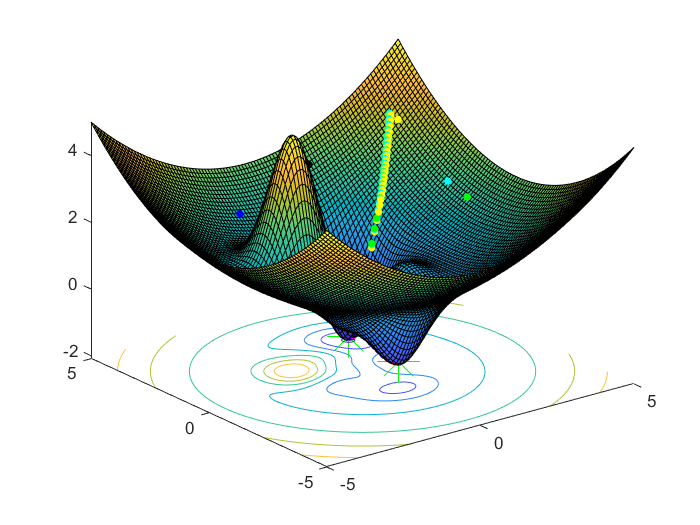

        x = X(1);
        y = X(2);
        z = ma_function(x,y);
        hold all;
        plot3(X(1), X(2), z+.1, '*g', 'MarkerSize', 25);
        
        % pour changer la couleur avec une nouvelle itération
        if compColor == 7
            compColor = 1;
    else
            compColor = compColor + 1;
        end
    end
end

Résultats obtenus grâce à la génération de points aléatoires appliquant l'algorithme dans un maillage de taille 5 :

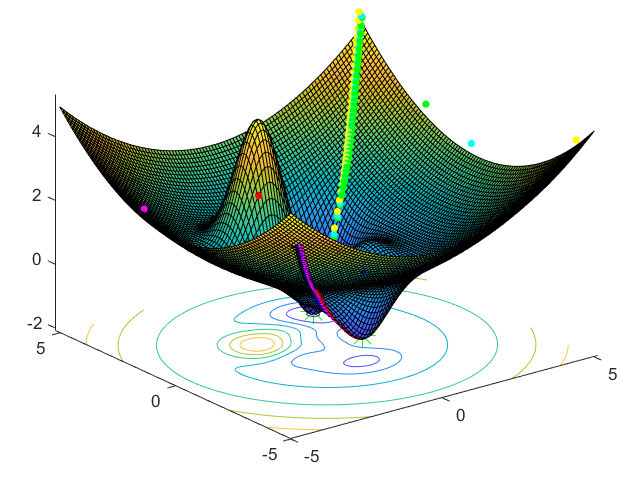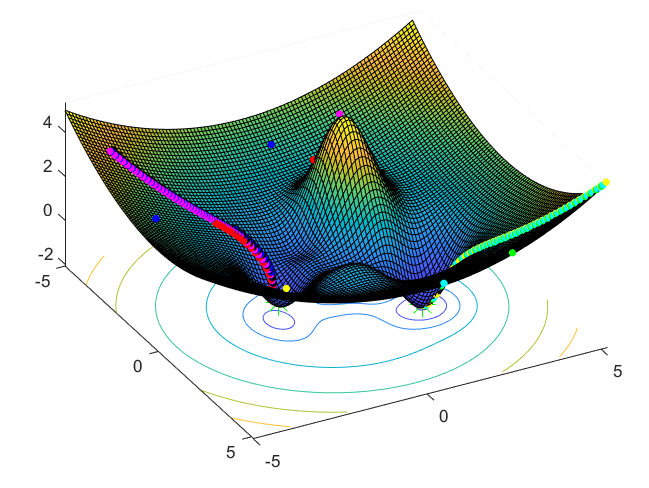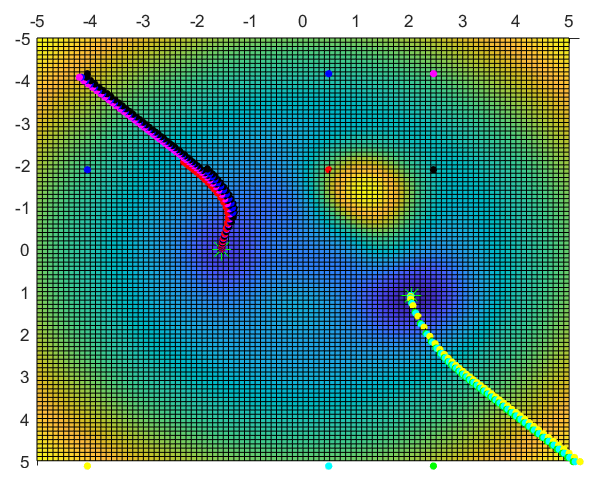    

    Selon l'endroit où l'algorithme commence à la surface, il peut converger ou non vers un minimum local. Différents points ont été générés et testés (chaque couleur c'est une application du algorithme avec un point initial diffèrent), et il est possible de remarquer que certains ne convergent pas vers le minimum local de la surface.

    Il est possible de remédier au problème en ajustant le pas à chaque itération, car le pas trop grand, peut finir par diverger, empêchant l'algorithme de trouver le point optimal. Si le pas est trop petit, à son tour, l'algorithme ne devient pas efficace, puisqu'il avance très peu à chaque itération.

### adaptation du pas à chaque itération

Mise à jour de l'algorithme précédemment implémenté, mise à jour de l'étape à chaque itération :

clear all; close all; clc;

Affichage de la fonction :

% définition de l'espace de travail :
intMesh = 5;
[x,y] = meshgrid(-intMesh:.1:intMesh, -intMesh:.1:intMesh);

% tracer la surface :
z = ma_function(x,y);
figure(1)
clf
hold on
surfc(x,y,z)
view(3)

Initialisation en testant différents points générés aléatoirement :

% Points X = (x,y)
var = 3; % n de points = carré de var

% points de départ :
x_coords = -(intMesh + 0.6)*rand(3,1) + (intMesh + 1)*rand(3,1) 

x_coords =     1.2615
    0.8591
    1.0184


y_coords = -(intMesh + 0.6)*rand(3,1) + (intMesh + 1)*rand(3,1)

y_coords =    -3.7153
   -3.0711
    2.0894


% définition des couleurs qui seront variées à chaque itération
C = {'.k','.b','.r','.g','.y','.c','.m'}; 
compColor = 1;

for i = 1:numel(x_coords)
    for j = 1:numel(y_coords)
        X = [x_coords(i),-y_coords(j)];
    
        % Choix du pas
        rho = 0.1;
       
        % définition du nombre maximal d'itérations
        compteur = 1;
        maxiter = 100;
        precision = 1.e-3;
        test = 1;
            
        while test
            compteur = compteur + 1;
            
            % Affichage progression de X
            x = X(1);
            y = X(2);
            z = ma_function(x,y);
            
            plot3(X(1), X(2), z + 0.1, C{compColor}, 'MarkerSize', 15);
            
            view([103.97 50.44])
            view(3)
            
            pause(.1)
            
            % Calcul du gradient
            g = gradient_ma_fonction(x,y);
        
            % Mise à jour de X
            Xold = X;
            % section éditée selon l'algorithme proposé
            %-----------------------------------
            X1 = X - (rho/2)*g;
            X2 = X - rho*g;
            X3 = X - 2*rho*g;
            XX = [X1;X2;X3];
            ZZ = [ma_function(XX(1), XX(2) )];
            minZ = min(ZZ);
            
            if minZ <= z         
                if minZ == ZZ(1)
                    X = X1;
                elseif minZ == ZZ(2)
                    X = X2; 
                else
                    X = X3;
                end     
            else
                rho = rho/4;
            end
            %-----------------------------------
            
            % test d'arrêt
            test = norm(Xold - X) > precision && compteur < maxiter;
        end
        
        % arrêté en raison du nombre maximal d'itérations atteintS
        if compteur == maxiter
            disp('warning: Nombre d"iteration maximum atteint')
        end

Affichage du dernier point :

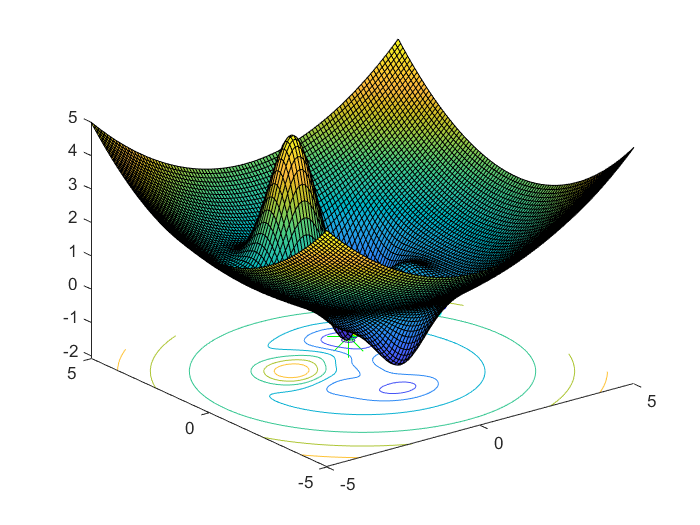

        x = X(1);
        y = X(2);
        z = ma_function(x,y);
        hold all;
        plot3(X(1), X(2), z+.1, '*g', 'MarkerSize', 25);
        
        % pour changer la couleur avec une nouvelle itération
        if compColor == 7
            compColor = 1;
    else
            compColor = compColor + 1;
        end
    end
end

Résultats obtenus grâce à la génération de points aléatoires appliquant l'algorithme dans un maillage de taille 5 :

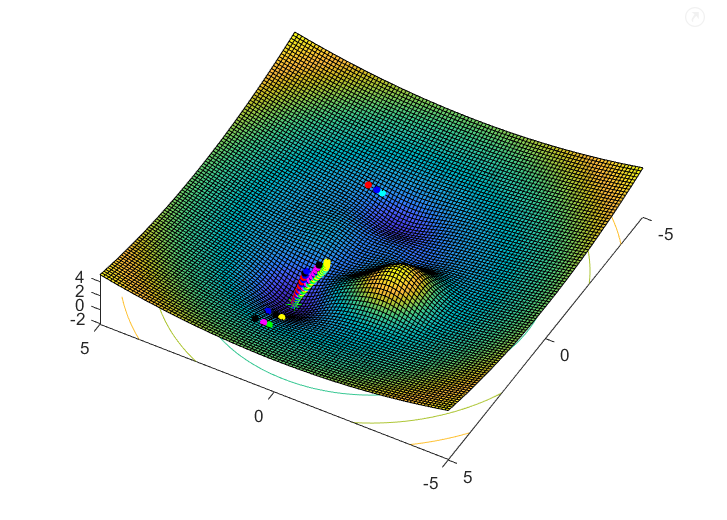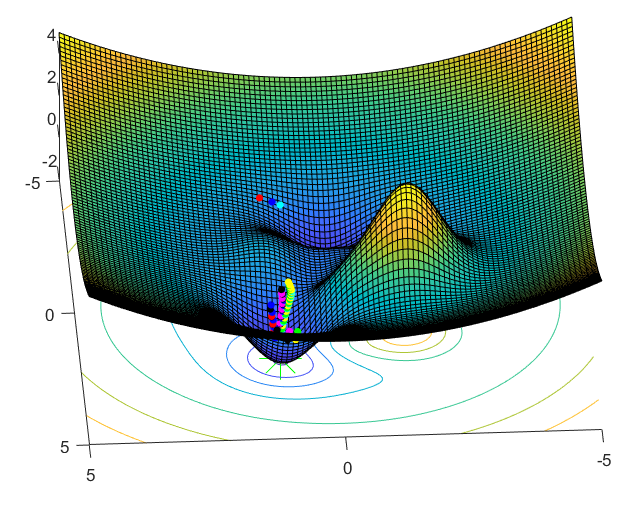      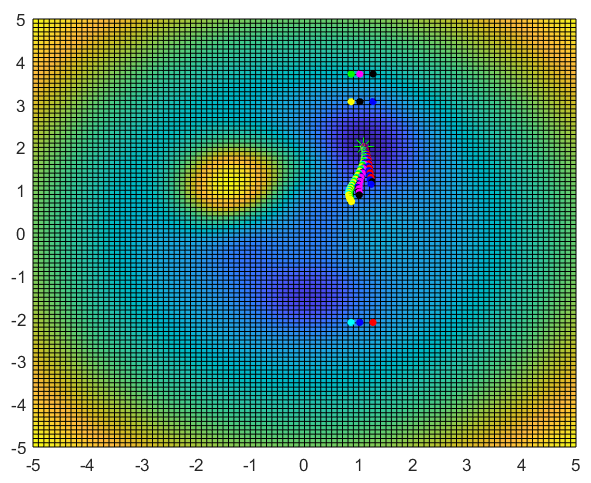

En adaptant le pas à chaque itération, il est possible de corriger le problème décrit précédemment, puisque nous proposons un pas suffisamment grand pour que l'algorithme avance vers un minimum local, mais pas trop grand, le faisant s'écarter de la solution. On peut voir que tous les points ont convergé vers un minimum local dans cettes simulations.

##  l’algorithme du gradient projeté 

    Avec A = [-1, 1] et b = 1, on a l'inégalité suivante : y - x >= 1, qui représente le domaine.

    Le domaine est convexe car en prenant deux points A et B appartenant au domaine, le segment [A, B] qui les joint est entièrement contenu dans celui-ci.

Modification de l'algorithme précédent et ajout des contraintes

clear all; close all; clc;

Affichage de la fonction :

% définition de l'espace de travail :
intMesh = 5;
[x,y] = meshgrid(-intMesh:.1:intMesh, -intMesh:.1:intMesh);

% tracer la surface :
z = ma_function(x,y);
figure(1)
clf
hold on
surfc(x,y,z)
view(3)

Initialisation en testant différents points générés aléatoirement :

% Points X = (x,y)
var = 3; % n de points = carré de var

% points de départ :
x_coords = -(intMesh + 0.6)*rand(3,1) + (intMesh + 1)*rand(3,1) 

x_coords =    -1.1275
    2.5531
   -1.6286


y_coords = -(intMesh + 0.6)*rand(3,1) + (intMesh + 1)*rand(3,1)

y_coords =     0.7850
   -0.3455
    1.1388


% définition des couleurs qui seront variées à chaque itération
C = {'.k','.b','.r','.g','.y','.c','.m'}; 
compColor = 1;

for i = 1:numel(x_coords)
    for j = 1:numel(y_coords)
        X = [x_coords(i),-y_coords(j)];
    
        % Choix du pas
        rho = 0.1;
       
        % définition du nombre maximal d'itérations
        compteur = 1;
        maxiter = 100;
        precision = 1.e-3;
        test = 1;
            
        while test
            compteur = compteur + 1;
            
            % Affichage progression de X
            x = X(1);
            y = X(2);
            z = ma_function(x,y);
            
            plot3(X(1), X(2), z + 0.1, C{compColor}, 'MarkerSize', 15);
            
            view([103.97 50.44])
            view(3)
            
            pause(.1)
            
            % Calcul du gradient
            g = gradient_ma_fonction(x,y);
        
            % Mise à jour de X
            Xold = X;
            % section ajoutée 
            %-----------------------------------
            X1 = X - (rho/2)*g;
            X2 = X - rho*g;
            X3 = X - 2*rho*g;
            XX = [X1;X2;X3];
            ZZ = [ma_function(XX(1), XX(2) )];
            minZ = min(ZZ);
            
            if minZ <= z         
                if minZ == ZZ(1)
                    X = X1;
                elseif minZ == ZZ(2)
                    X = X2; 
                else
                    X = X3;
                end     
            else
                rho = rho/4;
            end
            %-----------------------------------
            
            % implementation du gradient projeté
            %-----------------------------------
            A = [-1,1];
            b = 1;
            X = X';
            if (A*X - b<0)
                X = X + A'*(inv(A*A'))*(b - A*X);
            end 
            X = X';
            %-----------------------------------
            
            % test d'arrêt
            test = norm(Xold - X) > precision && compteur < maxiter;
        end
        
        % arrêté en raison du nombre maximal d'itérations atteintS
        if compteur == maxiter
            disp('warning: Nombre d"iteration maximum atteint')
        end

Affichage du dernier point :

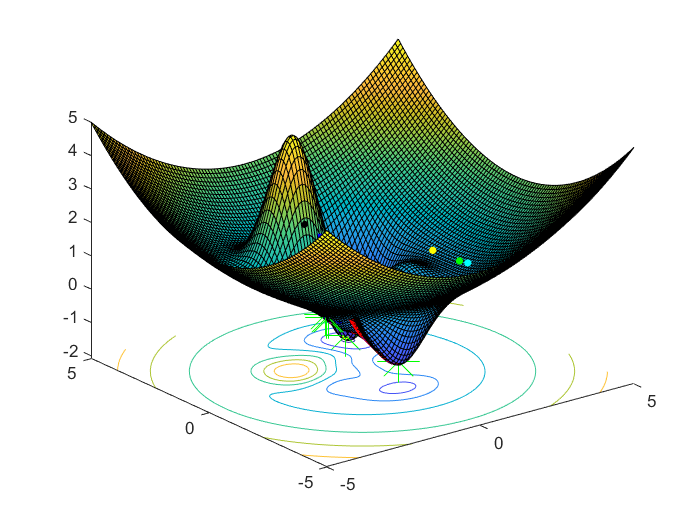

        x = X(1);
        y = X(2);
        z = ma_function(x,y);
        hold all;
        plot3(X(1), X(2), z+.1, '*g', 'MarkerSize', 25);
        
        % pour changer la couleur avec une nouvelle itération
        if compColor == 7
            compColor = 1;
    else
            compColor = compColor + 1;
        end
    end
end

Résultats obtenus grâce à la génération de points aléatoires appliquant l'algorithme dans un maillage de taille 5 :

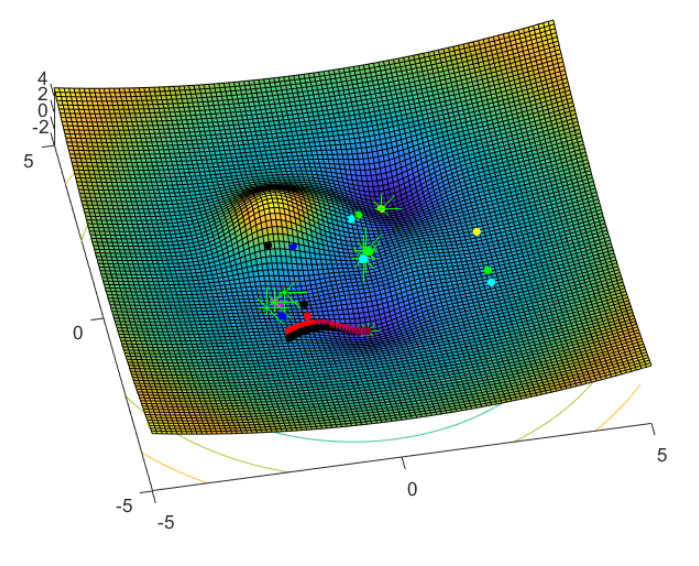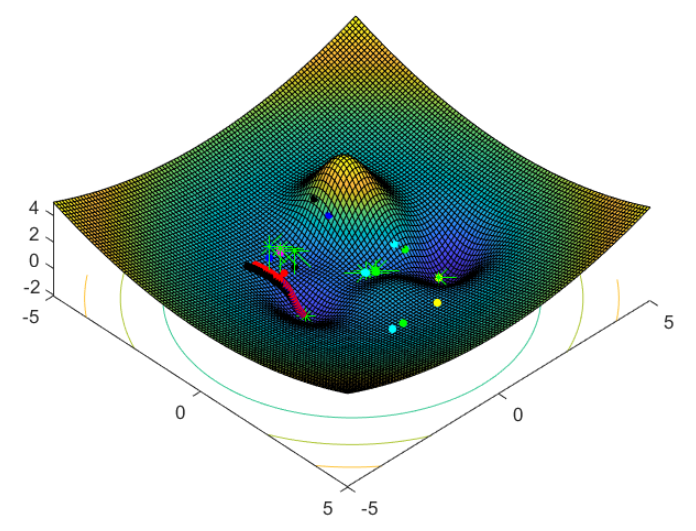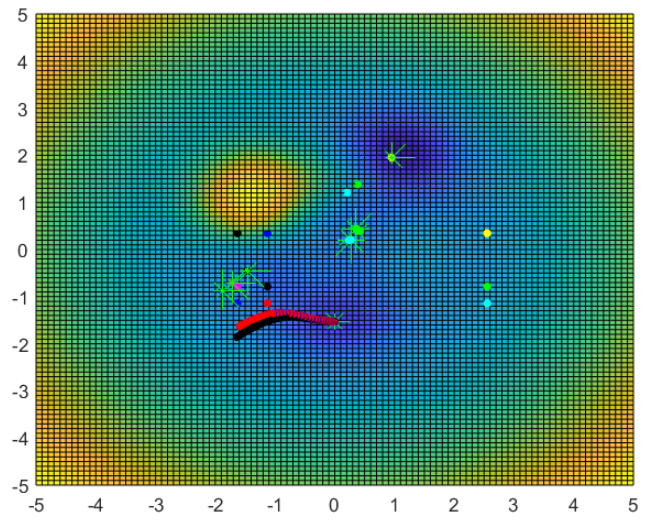

    On peut noter que l'algorithme développé approxime les points initiaux d'un minimum local mais n'arrive pas exactement au minimum local. C'est le résultat obtenu par les simulations de 9 points générés aléatoirement. Nous pouvons voir les points de convergence finaux grâce aux étoiles vertes générées dans les graphiques.

## l’algorithme d’Uzawa

Appliquant l'algorithme donné par le document avec les questions proposées.

clear all; clc;

Affichage de la fonction

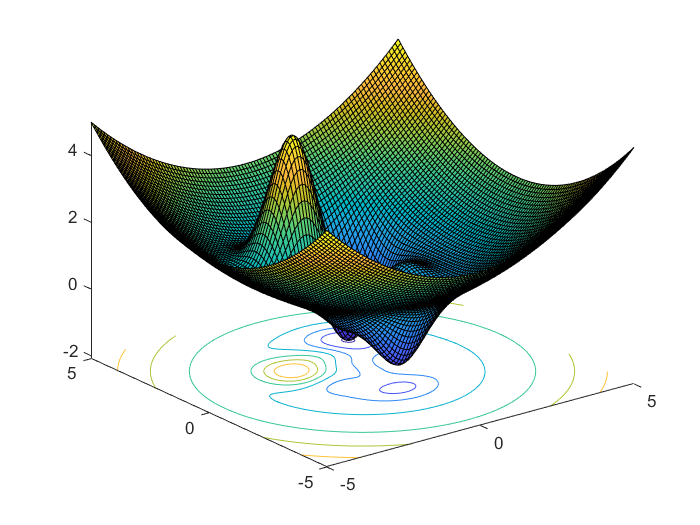

% définition de l'espace de travail :
intMesh = 5;
[x,y] = meshgrid(-intMesh:.1:intMesh, -intMesh:.1:intMesh);

% tracer la surface :
z = ma_function(x,y);
figure(1)
clf
hold on
surfc(x,y,z)
view(3)

Tracer de la contrainte $4 = y^2 + \frac{9}{4} x^2$ :

theta = 0:2*pi/200:2*pi;
x = 4/3*cos(theta);
y = 2*sin(theta);
z = ma_function(x,y);
figure(1)
plot3(x,y,z+.5,'b','MarkerSize',15)

% Nombre itérations maximum
maxiter = 100;

for theta = 2*pi/10:2*pi/10:2*pi

Point de départ

    X = 3*[cos(theta);sin(theta)];
    lambda = 0;

calcule minimum de L par rapport X

    [Fval,X] = minimum_L(X,lambda); %(A Faire)
    L=Fval;

Initialisation boucle while

    rho = 1;
    compteur = 0;
    test = 1;

    while test && compteur<maxiter
        compteur = compteur+1;


Affichage point courant

        figure(1)
        x = X(1), y = X(2);
        z = ma_fonction(x,y); % Evaluation de la fonction f (A faire)
        plot3(X(1), X(2), z+.1, '.r', 'MarkerSize', 25)
        pause(0.1)

Iteration point 2 avec pas variable rho/2, rho, et 2 rho

        contx = contrainte(X); % Evaluation de c(X) : A faire
        lambda1=max(0,lambda-rho/2*contx);

        % Calcul point 1 pour lambda1
        [L1,X1] = minimum_L(X,lambda1);
        lambda2 = max(0,lambda-rho*contx);

        % Calcul point 1 pour lambda2
        [L2,X2] = minimum_L(X,lambda2);
        lambda3 = max(0,lambda-2*rho*contx);
        
        % Calcul point 1 pour lambda3
        [L3,X3] = minimum_L(X,lambda3);
        
        % Sélection du meilleur résultat
        [L,ind] = max([L1,L2,L3]);

mise à jour et adaptation du pas

        if ind == 1
            rho = rho/2;
            lold = lambda;
            lambda = lambda1;
            X = X1;
        elseif ind == 2
            lold = lambda;
            lambda = lambda2;
            X=X2;
        else
            lold = lambda;
            lambda = lambda3;
            rho = 2*rho;
            X = X3;
        end

test arret

        test = (norm(lold-lambda)>1.e-2);
    end

Affichage

    figure(1)
    x = X(1), y = X(2);
    z = ma_fonction(x,y);
    plot3(X(1), X(2), z+.2, '*g', 'MarkerSize', 15)

Alerte arret prematuré

    if compteur == maxiter
        disp('warning: Nombre d"iteration maximum atteint')
    end
end

## fonctions utilisées

Fonctions implémentées ci-dessous utilisées dans les algorithmes ci-dessus :

function f = ma_function(x,y)
    f = -3.*exp(-(x-1).^2-(y-2).^2) + ((1-x).^2).*exp(-(x+1).^2-(y-1).^2)...
        - 2.*((x/5)-(x.^3)-(y.^5)).*exp(- x.^2 - y.^2)...
        - (1/2).*exp(-(x+1).^2 - y.^2) + 0.1.*(x.^2+  y.^2);    
end

function g = gradient_ma_fonction(x,y)
    g = [ x/5 + (exp(- (x + 1).^2 - y.^2).*(2.*x + 2))/2 ...
        + exp(- x.^2 - y.^2).*(6.*x.^2 - 2/5) ...
        + exp(- (x + 1).^2 - (y - 1).^2).*(2.*x - 2) ...
        + 3.*exp(- (x - 1).^2 - (y - 2).^2).*(2.*x - 2)...
        - 2.*x.*exp(- x.^2 - y.^2).*(2.*x.^3 - (2.*x)/5 + 2.*y.^5)...
        - exp(- (x + 1).^2 - (y - 1).^2).*(2.*x + 2).*(x - 1).^2, y/5 ...
        + y.*exp(- (x + 1).^2 - y.^2) + 10.*y.^4.*exp(- x.^2 - y.^2) ...
        + 3.*exp(- (x - 1).^2 - (y - 2).^2).*(2.*y - 4) ...
        - 2.*y.*exp(- x.^2 - y.^2).*(2.*x.^3 - (2.*x)/5 + 2.*y.^5) ...
        - exp(- (x + 1).^2 - (y - 1).^2).*(2.*y - 2).*(x - 1).^2]';
end

function [cval, aval] = contrainte(X)
    % Calcule cval la valeur de c(x) au point x et aval la valeur de gradient
    x = X(1);
    y = X(2);
    cval = 4 - (y^2 + (9/4)*(x^2));
    aval = gradient_ma_fonction(x,y);
end

function [Lval, Xval] = minimum_L(X,lambda)
    % Calcule par l’algorithme du gradient à pas variable le minimum
    % de la fonction Lagrangienne par rapport à X (lambda fixé).
    % Cette fonction utilise le calcul symbolique
    x = X(1);
    y = X(2);
    f = ma_function(x,y);
    syms x y lamda
    g = 4 - (y^2 + (9/4)*(x^2)) == 0; % contrainte 
    L = f + lambda * lhs(g); % Fonction de Lagrange
    dL_dx = diff(L,x) == 0; % dérivée de L par rapport à x
    dL_dy = diff(L,y) == 0; % dérivée de L par rapport à y
    dL_dlambda = diff(L,lambda) == 0; % dérivée de L par rapport à lambda
    system = [dL_dx; dL_dy; dL_dlambda]; % construire le système d'équations
    [Xval, Lval] = solve(system, [x y lambda], 'Real', true);
end